# Ejemplo solución analítica

clear;clc;

Se definen simbólicas las variables

syms t vc(t) il(t) R C L;

Se plantean las ecuaciones y se obtienen las matrices de la forma generalizada

M=[0 L;C 0]

$$M = \left(\begin{array}{cc} 0 & L\\ C & 0 \end{array}\right)$$

N=[-1 0;1/R 1]

$$N = \left(\begin{array}{cc} -1 & 0\\ \frac{1}{R} & 1 \end{array}\right)$$

u=[0;0]; 


$$u=\left(\matrix{0\cr0}\right)$$


Se expresan las matrices de la forma normalizada

A=-1.*(M\N)

$$A = \left(\begin{array}{cc} -\frac{1}{C\,R} & -\frac{1}{C}\\ \frac{1}{L} & 0 \end{array}\right)$$

Se definen las variables de estado

x=[vc;il]

$$x(t) = \left(\begin{array}{c} \mathrm{vc}\left(t\right)\\ \mathrm{il}\left(t\right) \end{array}\right)$$

Expresando el sistema en forma diferencial

odes = diff(x) == A*x

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{vc}\left(t\right)=-\frac{\mathrm{il}\left(t\right)}{C}-\frac{\mathrm{vc}\left(t\right)}{C\,R}\\ \frac{\partial }{\partial t}\mathrm{il}\left(t\right)=\frac{\mathrm{vc}\left(t\right)}{L} \end{array}\right)$$

Resolviendo el sistema con el comando dsolve

[vSol(t), iSol(t)] = dsolve(odes);

**Tensión del capacitor**

vSol(t) = simplify(vSol(t))

$$vSol(t) = C_{1}\,{\mathrm{e}}^{-\frac{t\,\left(L+\sqrt{L\,\left(L-4\,C\,R^{2}\right)}\right)}{2\,C\,L\,R}}+C_{2}\,{\mathrm{e}}^{-\frac{t\,\left(L-\sqrt{L\,\left(L-4\,C\,R^{2}\right)}\right)}{2\,C\,L\,R}}$$

**Corriente del inductor**

iSol(t) = simplify(iSol(t))

$$iSol(t) = \begin{array}{l} -\frac{C_{2}\,{\mathrm{e}}^{-\frac{t\,\left(L-\sigma_{1}\right)}{2\,C\,L\,R}}\,\left(L-\sigma_{1}\right)}{2\,C\,R}-\frac{C_{1}\,{\mathrm{e}}^{-\frac{t\,\left(L+\sigma_{1}\right)}{2\,C\,L\,R}}\,\left(L+\sigma_{1}\right)}{2\,C\,R}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{L\,\left(L-4\,C\,R^{2}\right)} \end{array}$$

Reemplazando los valores de R, L y C

clear C L R;
syms C1 C2;
R=1;L=1;C=1;
A=subs(A);

Las ecuaciones diferenciales son

odes = diff(x) == A*x

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{vc}\left(t\right)=-\mathrm{il}\left(t\right)-\mathrm{vc}\left(t\right)\\ \frac{\partial }{\partial t}\mathrm{il}\left(t\right)=\mathrm{vc}\left(t\right) \end{array}\right)$$

Definiendo las condiciones iniciales y tiempo de simulacion

v0=1;
i0=0;
ti=0;
tf=4*pi;
Xant=[v0;i0];
constantes=x(0)==Xant;
[vSol(t), iSol(t)] = dsolve(odes,constantes)

$$vSol(t) = \frac{2\,\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{3\,\sqrt{{\mathrm{e}}^{t}}}$$

$$iSol(t) = \frac{\cos\left(\frac{\sqrt{3}\,t}{2}\right)}{\sqrt{{\mathrm{e}}^{t}}}-\frac{\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{3\,\sqrt{{\mathrm{e}}^{t}}}$$

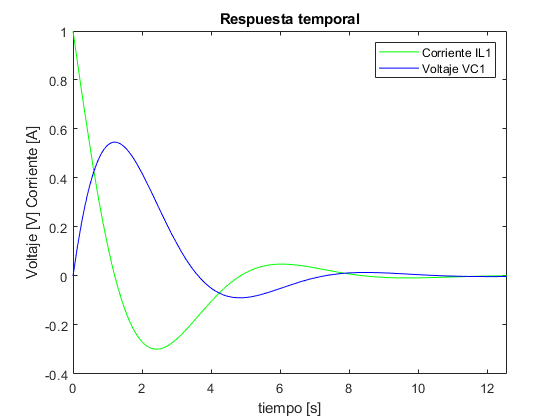

clf;
fplot(iSol,[ti,tf],'-g')

hold on
fplot(vSol,[ti,tf],'-b')
ylim([-0.4 1])
title('Respuesta temporal')
xlabel('tiempo [s]')
ylabel('Voltaje [V] Corriente [A]')
legend({'Corriente IL1','Voltaje VC1'})
hold off